# **demo08 of Im2mesh package**

demo08 - Parameter hmax for mesh generation

Cite as: Ma, J., & Li, Y. (2025). Im2mesh: A MATLAB/Octave package for generating finite element mesh based on 2D multi-phase image (2.1.5). Zenodo. [https://doi.org/10.5281/zenodo.14847059](https://doi.org/10.5281/zenodo.14847059)

Jiexian Ma, mjx0799@gmail.com

## Note

I suggest familiarizing yourself with Im2mesh_GUI before learning Im2mesh package. With graphical user interface, Im2mesh_GUI will help you better understand the workflow and parameters of Im2mesh package.

Im2mesh_GUI: [https://www.mathworks.com/matlabcentral/fileexchange/179684-im2mesh_gui-2d-image-to-finite-element-mesh](https://www.mathworks.com/matlabcentral/fileexchange/179684-im2mesh_gui-2d-image-to-finite-element-mesh)

If you are using Im2mesh package in MATLAB,  you need to install MATLAB Image Processing Toolbox and Mapping Toolbox because Im2mesh package use a few functions in these toolboxes.

## Setup

Before we start, please set folder "Im2mesh_Matlab" as your current folder of MATLAB.

clearvars

Set default image size.

x = 250; y = 250; width = 250; height = 250;
set(groot, 'DefaultFigurePosition', [x,y,width,height])
% To reset:
% set(groot, 'DefaultFigurePosition', 'factory')

Function im2mesh use a mesh generator called [MESH2D](https://github.com/dengwirda/mesh2d) (developed by Darren Engwirda). We can use the following command to add the folder 'mesh2d-master' to the path of MATLAB. 

addpath(genpath('mesh2d-master'))

## Transition

Let's start demo. Import image Transition.tif.

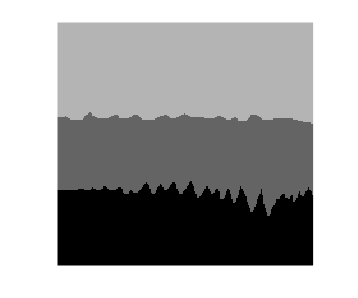

im = imread("Transition.tif");
if size(im,3) == 3;  im = rgb2gray( im ); end
imshow( im,'InitialMagnification','fit' );

Generate mesh.

opt = [];       % reset opt
opt.threshold_num_turning = 0;
opt.threshold_num_vert_Smo = 0;
opt.threshold_num_vert_Sim = 0;
opt.hmax = 8;

[ vert, tria, tnum ] = im2mesh( im, opt );

 Refine triangulation...

 -------------------------------------------------------
      |ITER.|          |CDT1(X)|          |CDT2(X)|     
 -------------------------------------------------------
          4                160                284
         10                202                882
         16                203                989


 Refine triangulation...

 -------------------------------------------------------
      |ITER.|          |CDT1(X)|          |CDT2(X)|     
 -------------------------------------------------------
         10                361                284
         13                373                284
         20                381               3867
         26                381               4493


 Smooth triangulation...

 -------------------------------------------------------
      |ITER.|          |MOVE(X)|          |DTRI(X)|     
 -------------------------------------------------------
          4               1280               4457
     

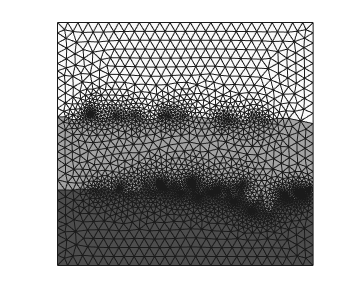

plotMeshes( vert, tria, tnum )

We can see that the max mesh size is limited by the parameter hmax.

## hmax

Let's use a much larger hmax to see how things are changing.

opt = [];       % reset opt
opt.threshold_num_turning = 0;
opt.threshold_num_vert_Smo = 0;
opt.threshold_num_vert_Sim = 0;
opt.hmax = 500;

[ vert, tria, tnum ] = im2mesh( im, opt );

 Refine triangulation...

 -------------------------------------------------------
      |ITER.|          |CDT1(X)|          |CDT2(X)|     
 -------------------------------------------------------
          4                160                284
         10                202                882
         16                203                989


 Refine triangulation...

 -------------------------------------------------------
      |ITER.|          |CDT1(X)|          |CDT2(X)|     
 -------------------------------------------------------
          7                330                284
         10                333               1832
         20                338               4107
         20                338               4107


 Smooth triangulation...

 -------------------------------------------------------
      |ITER.|          |MOVE(X)|          |DTRI(X)|     
 -------------------------------------------------------
          4               1225               4067
     

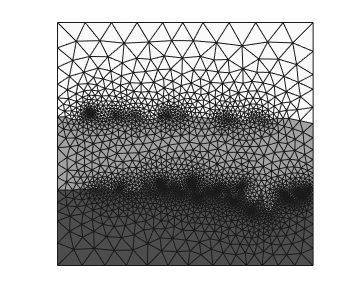

plotMeshes( vert, tria, tnum )

Now, the max mesh size is much larger. Note that hmax is a upper bound for the max mesh size. There exists boundary edge contraints and gradient-limt, so the max mesh size in the generated mesh can not reach hmax.

% reset image size
set(groot, 'DefaultFigurePosition', 'factory')

% end of demo